# ECE 1395 Project:

## Chess Evaluator

**Names:** Benjamin Bryla, Gabriel Yeniceri

clear; clc

## Thresholds

%Positin is classified as equal if within
IsEqual=75; %Position is equal if magnitude is inbetween +# and -#

%If checkmate exists, force evaluation to be
CheckmateThreshold=1000; %  [M-2] -> [-1000]

%Used as seed for RNG
RNG=123;


# Data Preprocessing:

#### Loading Data:

%Read filename and input into array
filename = "input\dataset_eval.csv";

%Options for getting CSV file read correct
options=detectImportOptions(filename);
options=setvartype(options,["Var2","Var4"],"string"); %Force strings, Eval: M1 does not give NaN value anymore
options.Delimiter = ',';
options.VariableNamingRule = 'preserve';

Data = readtable(filename, options);

#### Split data into Position and Evaluation

FEN = Data{:,2};
Eval = Data{:,4};

Column 1 and 3 are unneccessary. Column 1 is the game #, this will not influence training in any way. Column 3 is best move, the scope of the project will no longer contain the best move, instead it only contains evaluation. 

Cleanup

clearvars options filename Data

## Evaluation Pre-Process:

This part of the pre-processing will deal with the evaluation output. 

- If there is checkmate on board (denoted by M # or M- #) the evaluation is going to be set to some variable defined above. 

- The evaluation of each position is given relative to who's turn it is, + is winning for whoever's turn it is. The evaluation will be changed to absolute relative to white. + is winning for white no matter who's turn it is.

- The evaluation is also going to be turned into classes based on some threshold defined above, -1 black winning, 0 is within threshold, 1 white winning. Adding 2 to every column will change it to 1 is black winning, 2 is equal, 3 is white winning. 

%Modify mate on boards
is_M = contains(Eval(:),'M'); %If Mate is on Board
is_EvalMinus = ~contains(Eval(:),'-'); %If evaluation contains a - 

IsMate=((is_EvalMinus-0.5)*2).*is_M*CheckmateThreshold; %Mating Threat new evals
IsMateShort=IsMate(IsMate~=0);

%Change eval from Relative based on turn, to Absolute based on White
is_WhiteTurn = contains(FEN(:),'w'); %If is White's Turn

EvalAbsolute=(is_WhiteTurn-0.5)*2;

%Change Checkmate in # to Checkmate Threshold
Eval(is_M)=IsMateShort; 
%Change Relative eval to Absolute Eval
Eval=str2double(Eval);
Eval=Eval.*EvalAbsolute;

%Create Discrete Evaluation
Greater= Eval>=IsEqual;
Less= Eval<=-IsEqual;

EvalDiscrete=Greater-Less;

Cleanup

clearvars is_M is_M is_EvalMinus IsMate IsMateShort EvalAbsolute CheckmateThreshold Greater Less

## Bitboard Pre-Process:

Converts FEN notation to Bitboard Representation

%Splits bitboard into Board, and Extras
SplitFEN=split(FEN); %Index 1 is Board, Index 2-6 is extra information
%Board Split
Board=split(SplitFEN(:,1),'/');

BoardExtra=SplitFEN(:,2:end);

#### Written:

At this point we have the board, m x 8 string, each column represents a chess board column. BoardExtra is split up into 5 columns, turn, Castling rights, Enpassant rights, half move clock, full move number. 

cleanup

clearvars SplitFEN

## Bitboard Creation

FEN to Piece Board function. Takes in the board split from above

%Create a Piece Board
function PieceBoard=FEN2Piece(Board)
    PieceBoard=zeros(1,8*8);
    L=strlength(Board);
    for dataNum=1:height(Board) %For every data set
        CurrBoard = Board(dataNum,:);
        rowIndex=1;
        for column=1:8 %For every column of chess board
            CurrRow = CurrBoard(column);
            for row=1:L(dataNum,column) %For the rows of the chess board
                charRow=CurrRow{1}(row);
                if isstrprop(charRow, 'digit') %If number is found add it's value to index do not update the piece board
                    rowIndex = rowIndex + str2double(charRow);
                else %If character is found
                    PieceBoard(dataNum,rowIndex)=charRow; %If char is found, set char
                    rowIndex=rowIndex+1; %Increment

timeElapsed = 0.6381

                end

Time to convert 5000 FEN to bitboard: 0.63814


            end
        end
    end
end

Piece to Bit Board function

function BitBoard=Piece2Bit(Piece)
%List of pieces
pieceList='pbnrqkPBNRQK';
for m=1:height(Piece)
    BitBoard=false(height(Piece),8*8*12);
    for squareIndex=1:64 %Check every square for if it contains a piece
        for pieceIndex=1:12
            if pieceList(pieceIndex)==Piece(squareIndex)

index: 3651


                BitIndex=squareIndex+64*pieceIndex-64; %Calculate index of the bitboard square
                BitBoard(BitIndex)=1; %And set to true

Show the current board state


            end

r~bq~rk~
~p~~~ppp
p~~~pn~~
~~~p~~~~
~~~~~~~~
~P~BPN~~
~PP~~PPP
R~~QK~~R


        end
    end
end
end

p


   0   0   0   0   0   0   0   0
   0   1   0   0   0   1   1   1
   1   0   0   0   1   0   0   0
   0   0   0   1   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0



b


   0   0   1   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0



n


   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   1   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0



r


   1   0   0   0   0   1   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0



q


   0   0   0   1   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0



k


   0   0   0   0   0   0   1   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0



P


   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   1   0   0   1   0   0   0
   0   1   1   0   0   1   1   1
   0   0   0   0   0   0   0   0



B


   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   1   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0



N


   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   1   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0



R


   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   1   0   0   0   0   0   0   1



Q


   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   1   0   0   0   0



K


   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   1   0   0   0



Converts the Board representation into Bitboards

%Number of data points to use
m=height(Board);
m=5000;

%Setup Empty Arrays
Data=Board(1:m,:);
PieceBoard=zeros(height(Data),8*8);
BitBoard=false(height(Data),8*8*12);

%Convert to piece board
tic
for i=1:m
    PieceBoard(i,:)=FEN2Piece(Board(i,:));
    BitBoard(i,:)=Piece2Bit(PieceBoard(i,:));
end
timeElapsed=toc
fprintf("Time to convert %d FEN to bitboard: %0.5f\n",m,timeElapsed)

%Convert to Char
PieceBoard=char(PieceBoard);
%Fill in Empty
PieceBoard(PieceBoard==0)='~';

Cleanup

clearvars Data timeElapsed i Board

## FEN Conversion Verification

Testing: Check current board state based on index

index=3651;
disp("index: "+index)
ShowBoard=reshape(PieceBoard(index,:),8,8)'; %Convert from Piece Board into 8x8
disp("Show the current board state")
disp(ShowBoard)

pieceList='pbnrqkPBNRQK';
for i=0:11 %Each Piece
    disp(pieceList(i+1))
    disp(reshape(BitBoard(index,64*i+1:64*i+64),8,8)') %Convert from Bit Board into 12x8x8
end

Cleanup

clearvars index ShowBoard disp i

Example at Index 285; Comparing Chess.com vs Matlab; The current board state in an array that represents the same boardstate as chess.com's FEN analysis. 

Data Set: Eval = -358: EvalDiscrete = -1 (black winning). 

Chess.com Evaluation -3.47, -1 (black winning) , depth 17, 3 seconds. This 100x scaling in the data set is used to removing the decimal. 

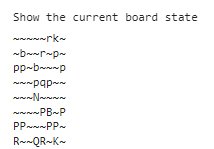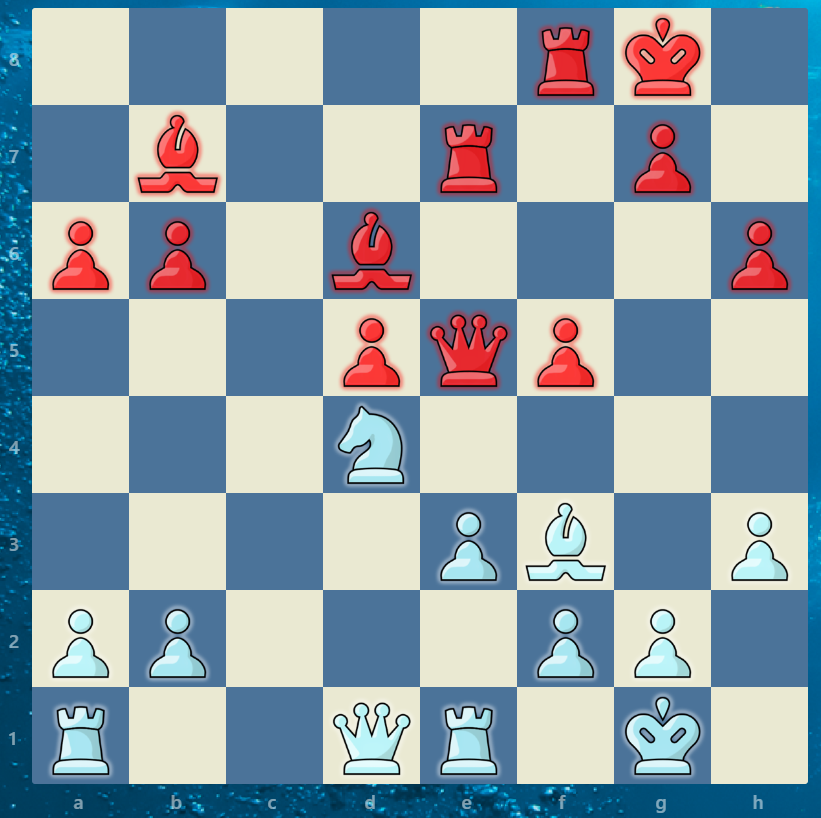

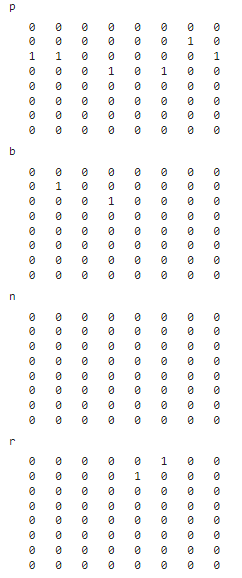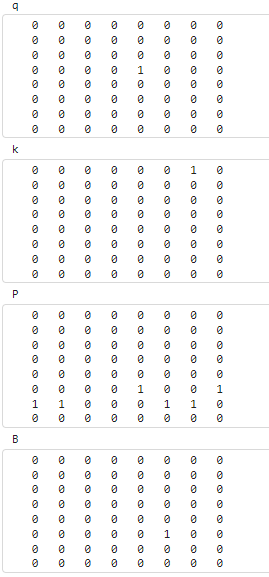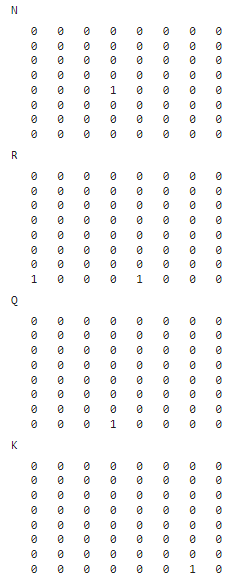

When looking at the bit board, it aligns with the location of pieces for FEN notation. Lowercase = Black pieces. Uppercase = White Pieces. The position is aligned with the standard chess board position. K is White's King, in both the bit board, piece board, and chess.com it is shown in the G1 square. p is Black's Pawns, the structure is the same in all 3 representations. n is Black's Knights, the bitboard is all 0's because black does not have a knight. 

## FEN Extra Data

FEN notation has 5 additional bits of information that need to be dealt with. 

It is split up into the BoardExtra variable, they were all separated prevously by the space demileter

Column 1: Who's turn it is. b=black, w=white

Will be represented by a 1=white, 0=black

is_WhiteTurn; %Already created when coverting from relative to absolute evaluation. 

Column 2: KQkq, Castling legality, K=White king side castle, Q=White Queen Side Caste. kq are same but for black;

Column 3: En-Passant Rights, if a piece can enpassant, this is the square it can go to. 

1=Can EnPassant, 0=Cannot. This is unlikely to have many data points (417, ~0.12%), in addition it is not a critical portion of an evaluation, a true/false value should suffice for our use. Any non '-' value will be set to 1 for can en-passant. 

is_EnPassant=BoardExtra(:,3)~='-';

Column 4: Half-Move Clock. Counts up by 1 every half move (white OR black moves), resets to 0 every time there is a, capture, or pawn move. This is from the 50 move rule in chess where if neither side captures, or makes a pawn move the game is a draw;

Convert to Double: 

HalfMove=str2double(BoardExtra(:,4));

Column 5: Full Move Counter. after white AND Black has moves, ticks up by 1. How many moves the game has been;

Convert to Double: 

FullMove=str2double(BoardExtra(:,5));